clear
clc
close all

# MPEG LAYER II

### Read File:

file = 'project.wav';
[signal,Fs] = audioread(file);
file_info = audioinfo(file)

file_info = struct with fields:
             Filename: 'D:\OneDrive - Zewail City of Science and Technology\UST\Year 4\Fall\DSP\Mini_project\mpeg\MPEG-Audio-Compression\project.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 240000
             Duration: 10
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


bps = file_info.BitsPerSample;
sound(signal,Fs);

### Get Filter Coefficients

num_filters= 32;
filter_order=512;
h_all = zeros(num_filters,filter_order);
h_coeffs = PQMF_ReadCoeffs();

L = 257

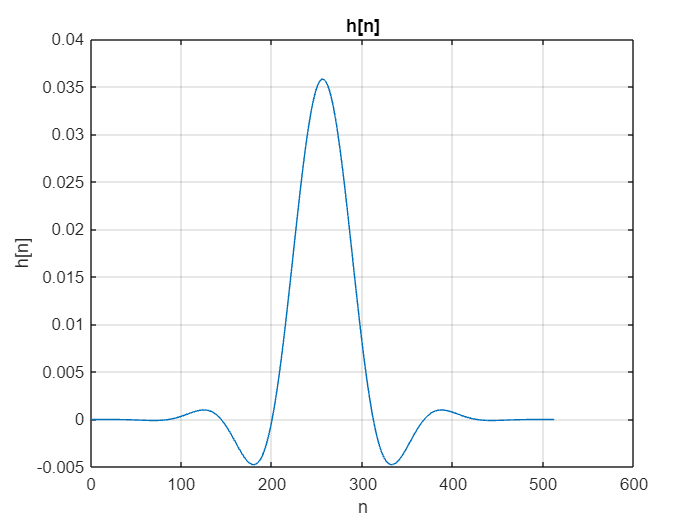

plot([0:512],h_coeffs)
grid on
title('h[n]')
xlabel('n')
ylabel('h[n]')

### Getting all modulated filters:

According to this equation:

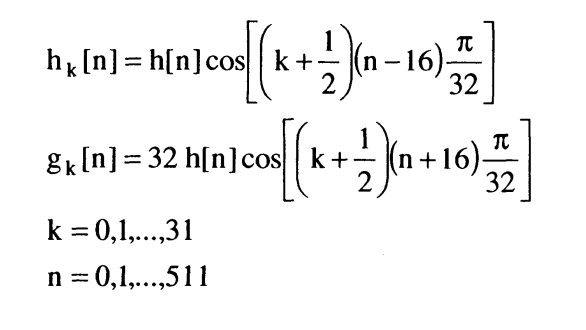

(Bosi, Goldberg, sect 4.2)

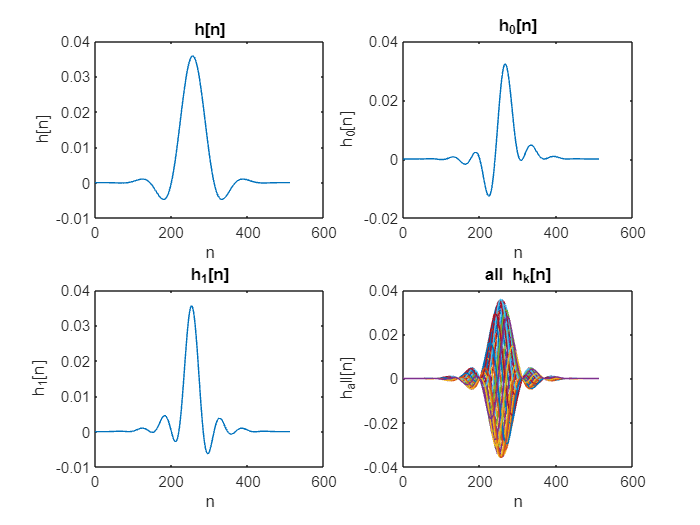

for k= 0 :num_filters-1
    for n=0: filter_order-1
        h_all(k+1,n+1) = h_coeffs(n+1) * cos((k+(1/2)*(n-16)*(pi/32)));
    end
end

subplot(2,2,1)
plot([0:511],h_coeffs(1:512))
title('h[n]')
xlabel('n')
ylabel('h[n]')
subplot(2,2,2)
plot([0:511],h_all(1,:))
title('h_0[n]')
xlabel('n')
ylabel('h_0[n]')
subplot(2,2,3)
plot([0:511],h_all(2,:))
title('h_1[n]')
xlabel('n')
ylabel('h_1[n]')
subplot(2,2,4)
plot([0:511],h_all)
title('all h_k[n]')
xlabel('n')
ylabel('h_all[n]')

### Now, Let's filter the signal:

sig_filtered =[];
for k=0:1:31
    sig_f= filter(h_all(k+1,:),1,signal);  %Filtering 
    sig_down = downsample(sig_f,32);       %Down Sampling
    sig_filtered=[sig_filtered sig_down];  %Appending
end

# `Psychoacoustic Model `

# `Computing SPL`

### Signal Spectrum after FFT

close all

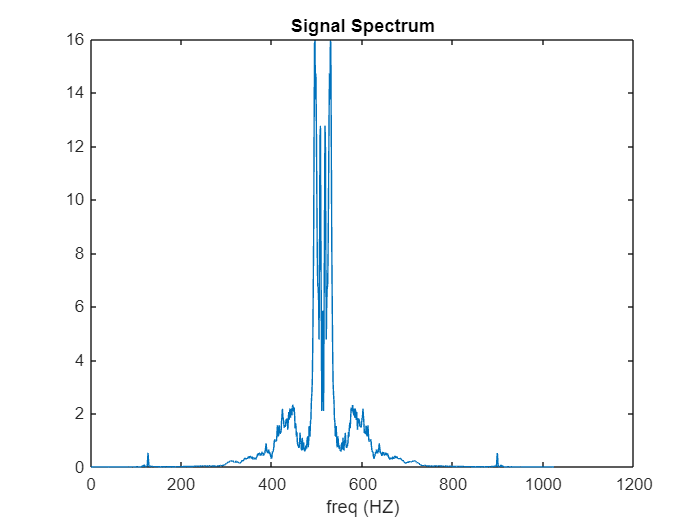

X = load('Signal_Spectrum.mat');
Signal_Spectrum = (X.Signal_Spectrum);
n = 0:length(Signal_Spectrum)-1;
plot(n,Signal_Spectrum)
xlabel('freq (HZ)')
title('Signal Spectrum')

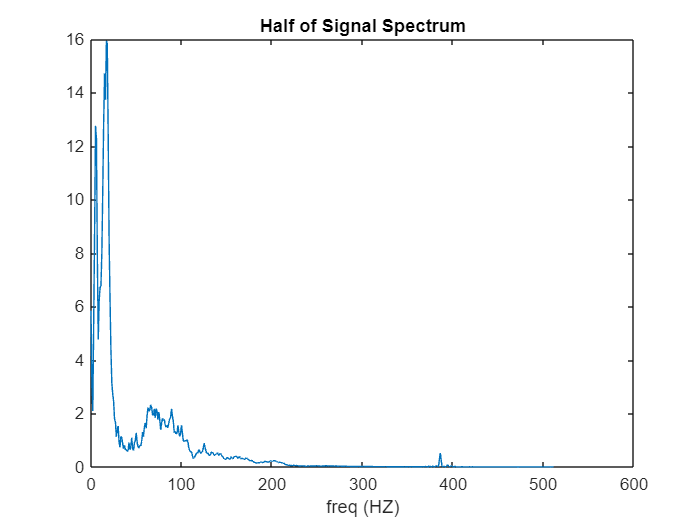

half_spectrum = X.Signal_Spectrum(513:end);
n = 0:length(half_spectrum)-1;

plot(n,half_spectrum)
xlabel('freq (HZ)')
title('Half of Signal Spectrum')

N = 1024;
f_vector = linspace(-Fs/2,Fs/2,N);
half_freq = f_vector(N/2+1:end);

### SPLs computing and evaluating

Lk = Lk_fn(N,half_spectrum);
q_threshold = threshold_in_quiet(half_freq);

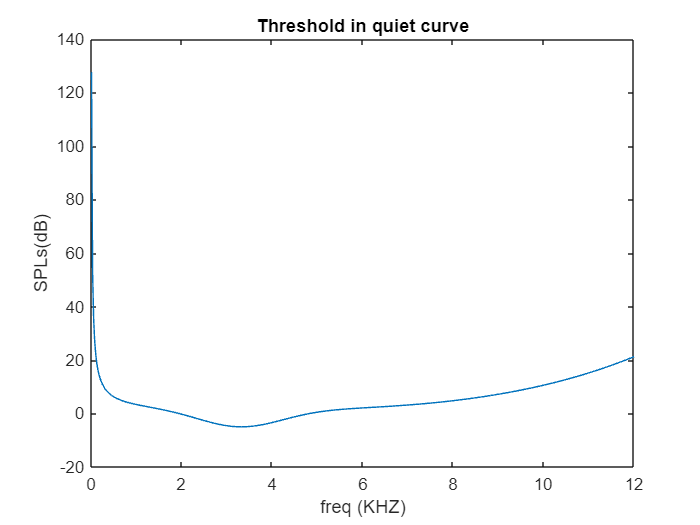


plot(half_freq/1000,q_threshold);
title('Threshold in quiet curve')
xlabel('freq (KHZ)')
ylabel('SPLs(dB)')

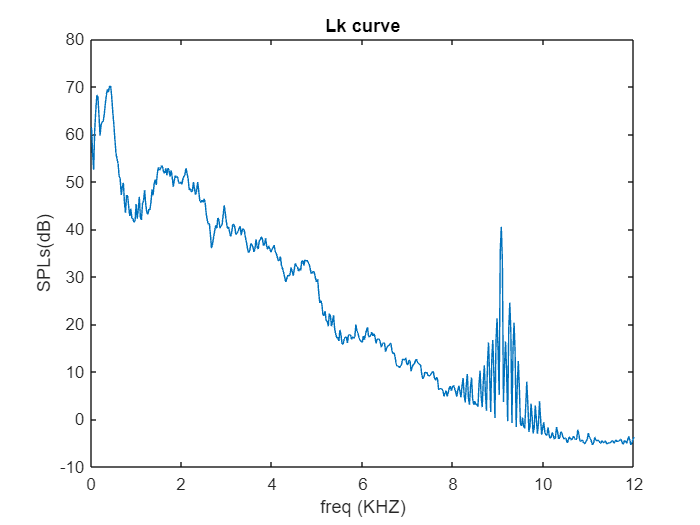

plot(half_freq/1000,Lk);
title('Lk curve')
xlabel('freq (KHZ)')
ylabel('SPLs(dB)')

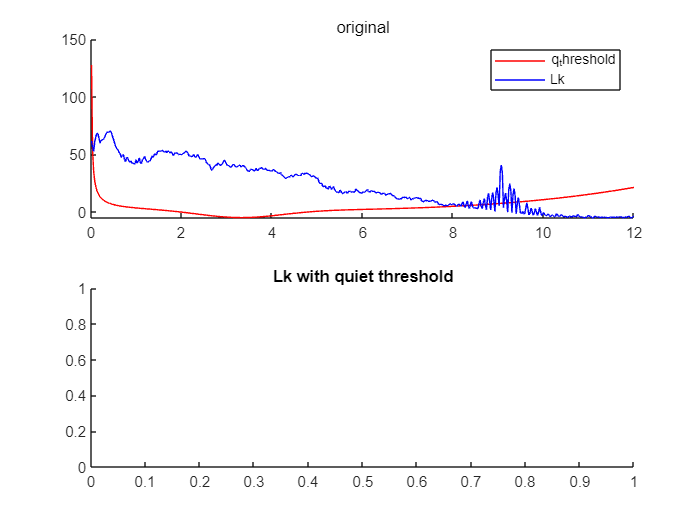


subplot(2,1,2);
title('Lk with quiet threshold');

subplot(2,1,1);

subtitle('original')
hold on
plot(half_freq/1000,q_threshold,Color='r');
plot(half_freq/1000,Lk,Color='b');
legend({'q_threshold','Lk'})
hold off

% set zeros to Lks that is less than the quite threshold
indices = q_threshold>Lk;
Lk(indices) = 0;

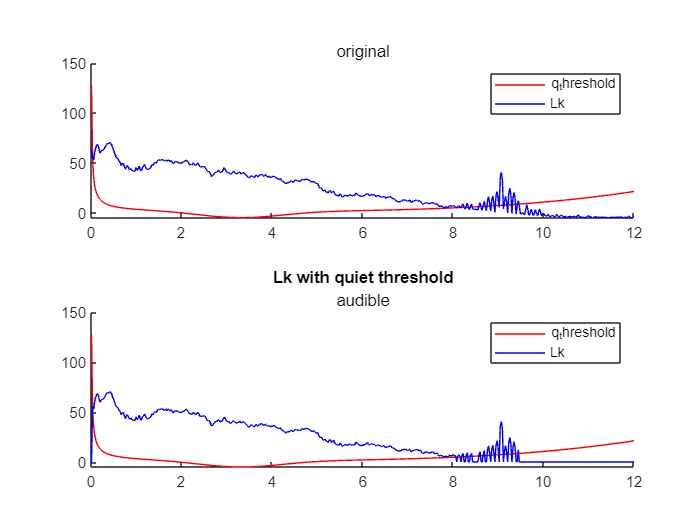

subplot(2,1,2);
subtitle('audible')
hold on
plot(half_freq/1000,q_threshold,Color='r');
plot(half_freq/1000,Lk,Color='b');
legend({'q_threshold','Lk'})
hold off

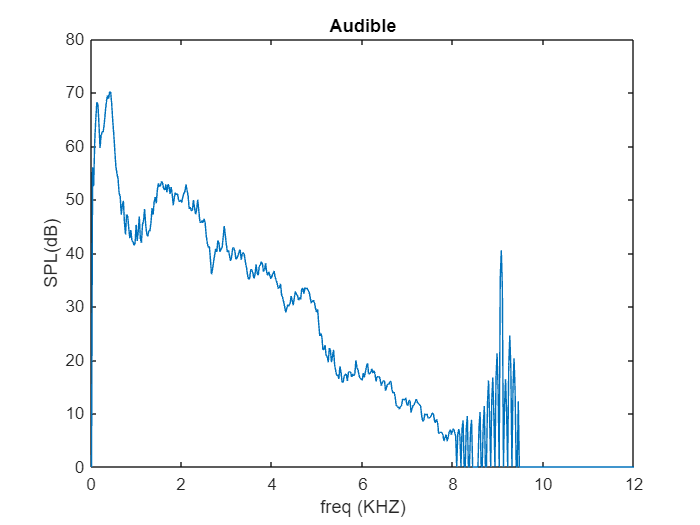

close all
plot(half_freq/1000,Lk);
title('Audible')
xlabel('freq (KHZ)')
ylabel('SPL(dB)')

# `Psychoacoustic Model `

# Separation of Tonal & Non-Tonal Components

sub_num = 32;
SPL_matrix = vector2matrix(Lk,sub_num);
freq_matrix = vector2matrix(half_freq,sub_num);

for i = 1 : sub_num
    % the SPL and the freq of the i sub-band
    sub_band_SPL  = SPL_matrix(i,:);
    sub_band_freq = freq_matrix(i,:);
    % get the golobal and local maximas 
    [peakValues, peakIndices] = Find_maximas(sub_band_SPL);     % peakValues is the spl value
                                                                % peakIndices is its position                  
    % looping over the peaks in the sub-band
    for j = 1: length(peakValues)

        % set the masker freq and its SPL
        masker_freq = sub_band_freq(peakIndices(j));
        masker_SPL  = peakValues(j);
        % check that SPL of the masker is not zero
        if masker_SPL ~= 0
            % calculate the most right freq affected by the masker
            f2 = masking_threshold(masker_SPL,masker_freq);
            % and its SPL
            f2_SPL = threshold_in_quiet(f2);
            % Two points to interp the spreading function
            y_spl  = [masker_SPL f2_SPL];          
            x_freq = [masker_freq f2];
            % p = spreading_fn(x,y);
            p = polyfit(x_freq,y_spl,1);
            delta = 1.5;
            p = p*delta;
            
            % looping over the affected part of the sub-band
            for k = peakIndices(j)+1 : 16
                if sub_band_freq(k) < f2
                    % get the masking threshold for tonal components
                    m_threshold = polyval(p,sub_band_freq(k));
                    if sub_band_SPL(k) < m_threshold
                        sub_band_SPL(k)=0;
                    end
                end
            end
            
        end
    end
    SPL_matrix(i,:) = sub_band_SPL;
end

Lk_after_masking = matrix2vector(SPL_matrix);

Lk_after_masking =          0   56.0346         0         0         0         0         0         0         0         0         0         0         0         0         0         0   68.8269   70.1209         0         0         0         0         0         0         0         0         0         0         0         0         0         0   43.4762   47.1908         0         0         0         0         0         0         0         0         0         0         0         0         0         0   45.3011   46.0320


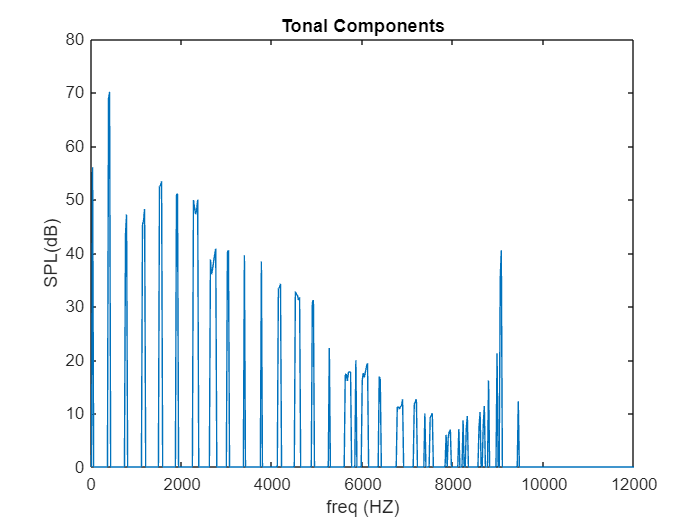

plot(half_freq,Lk_after_masking);
title('Tonal Components');
xlabel('freq (HZ)');
ylabel('SPL(dB)');

sig_filtered_matrix=sig_filtered.';

% get the FFT to the output of the filter bank
sig_filtered_fft = zeros(32,1024);
for i = 1:sub_num  
    sig_filtered_fft(i,:) = abs(fftshift(fft(sig_filtered_matrix(i,:),1024))); 
end


% get half the FFT output 
half_sig_filtered_fft = sig_filtered_fft(:,513:end);

% calc the SPLs for each sub-band
SPLs_sig_filtered = Lk_fn(1024,half_sig_filtered_fft);

% apply masking
sig_filtered_masked = SPLs_sig_filtered.*Lk_after_masking;

% calc the sum of sub-bands SPLs
sum_spl = sum(sig_filtered_masked,2).'

sum_spl = 1.0e+04 *

    7.7862    8.0441    7.5118    7.6831    8.0396    7.6503    7.5569    8.0201    7.7684    7.4212    7.9963    7.8665    7.2877    7.9702    7.9421    7.2345    7.9298    7.9959    7.2306    7.8709    8.0293    7.3088    7.7919    8.0438    7.5020    7.6903    8.0403    7.6424    7.5653    8.0216    7.7616    7.4294


% bit allocation
sub_band_bits = bit_allocation(16,sum_spl)

sub_band_bits =      2    16     1     2    16     1     1     6     2     1     6     2     1     2     2     1     2     2     1     2     6     1     2    16     1     2    16     1     1     6     2     1


ans = 625

% quantization
% cols = size(sig_filtered_matrix,2)/12;
% rows = 32;
% quantized = [];
% % looping over the cols
% current_index = 1;
% for j = 1:12:size(sig_filtered_matrix,2)
%     for i = 1:size(sig_filtered_matrix,1)
%         array = [];
%         [maxi,mini,array] = Quan(sig_filtered_matrix(i,j:j+12),sub_band_bits(i));
%         array
%         s = struct('max',maxi,'min',mini,'quantization',array)
%         quantized = [quantized s];
%         current_index = current_index + 1;
%     end
% end

array =      3     3     3     3     3     3     3     3     3     1     1     0     0


s = struct with fields:
             max: 0.0017
             min: -0.0066
    quantization: [3 3 3 3 3 3 3 3 3 1 1 0 0]
